casovniKorak = 0.01;
% Parametri simulacije
Ts = 0.01;  % Vzorec (Sample time)
N_sim = 10000;  % Število simulacijskih korakov
H = 4;  % Število upoštevanih členov

% Naloži Takagi-Sugeno model
load('ts.mat');  % Nalaganje modela iz datoteke

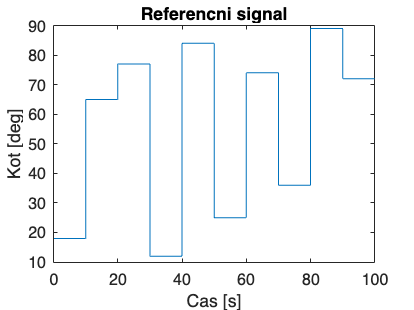


% Referenčni sistem (1. reda)
s = tf('s');
G_ref = 4 / (s + 4);  % Prenosna funkcija referenčnega sistema
sys_ref = c2d(G_ref, Ts, 'zoh');  % Diskretizacija referenčnega sistema
[A_ref, B_ref, C_ref, ~] = ssdata(sys_ref);

% Ustvarjanje referenčnega signala
cas = 0:casovniKorak:99.99;
steviloTock = length(cas);
referencniSignal = zeros(1, steviloTock);
amplitude = [18, 65, 77, 12, 84, 25, 74, 36, 89, 72];
casovniInterval = steviloTock / length(amplitude);

for i = 1:length(amplitude)
    zacetek = (i - 1) * casovniInterval + 1;
    konec = i * casovniInterval;
    referencniSignal(zacetek:konec) = amplitude(i);
end
figure;
plot(cas, referencniSignal);
title("Referencni signal");
xlabel("Cas [s]");
ylabel("Kot [deg]");

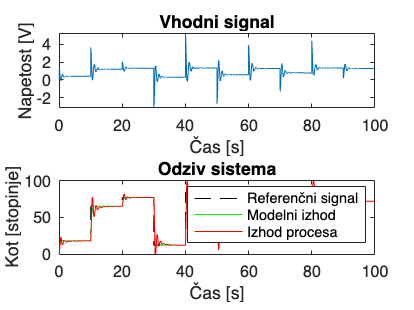


% Inicializacija stanj in vhodnih signalov
x_ref = 0;
x_model = [0; 0];
x_process = [0; 0];
u = zeros(1, N_sim);
y_model = zeros(1, N_sim);
y_process = zeros(1, N_sim);
y_ref = zeros(1, N_sim);

% Koeficienti za funkcijski regulator
for k = 3:N_sim
    % Izračun napake
    y_ref(k) = C_ref * x_ref;  % Izhod referenčnega sistema
    e = referencniSignal(k) - y_process(k-1);  % Napaka glede na proces

    % Izračunovanje matrik sistema na podlagi TS modela za trenutno stanje modela
    [A_m, B_m, C_m, R_m] = TS2SS(C, O, W, b, [-y_process(k-1); -y_process(k-2)]);

    % Prediktivni regulator
    G0 = C_m * (A_m^H - eye(size(A_m))) * pinv(A_m - eye(size(A_m))) * B_m;
    G = pinv(G0) * (1 - A_ref^H);

    % Krmilni signal
    u(k) = G * e + pinv(G0) * y_model(k-1) - pinv(G0) * C_m * (A_m^H) * x_model - pinv(B_m) * R_m;

    % Posodobitev stanj za referenčni, modelni in procesni sistem
    x_ref = A_ref * x_ref + B_ref * referencniSignal(k);
    x_model = A_m * x_model + B_m * u(k) + R_m;
    y_model(k) = C_m * x_model;

    % Procesni model (Helicrane)
    [x_process(2), x_process(1)] = helicrane(u(k), x_process);
    y_process(k) = x_process(2);
end

% Prikaz rezultatov
figure;
subplot(2, 1, 1);
plot(cas, u);
title('Vhodni signal');
xlabel('Čas [s]');
ylabel('Napetost [V]');

subplot(2, 1, 2);
plot(cas, referencniSignal, 'k--');
hold on;
plot(cas, y_ref, 'g');
plot(cas, y_process, 'r');
legend('Referenčni signal', 'Modelni izhod', 'Izhod procesa');
title('Odziv sistema');
xlabel('Čas [s]');
ylabel('Kot [stopinje]');

function [A_m, B_m, C_m, R_m] = TS2SS(C, O, W, b, x)
    % Pretvori Takagi-Sugeno model v stanjskoprostorski model
    
    R = size(C, 1);  % Število pravil (rules)
    A_m = zeros(2, 2);
    B_m = zeros(2, 1);
    C_m = zeros(1, 2);
    R_m = zeros(2, 1);

    % Izračun vrednosti membership funkcij
    mu = exp(-0.5 * sum((x' - C).^2 ./ (O.^2), 2));
    mu = mu / sum(mu);  % Normalizacija

    % Sestavljanje stanjskih matrik s ponderiranjem
    for i = 1:R
        A_m = A_m + mu(i) * [0, -W(i,4); 1, -W(i,3)];
        B_m = B_m + mu(i) * [W(i,2); W(i,1)];
        C_m = C_m + mu(i) * [0, 1];
        R_m = R_m + mu(i) * [0; b(i)];
    end
end
